# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 구은총**

**학번**** : 201710871**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

n = 0:3;
xn = [1 2 2 1];
N = 4;
Xk = dft(xn,N)

Xk =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i


figure();
subplot(2,2,1);
stem(0:N-1,abs(Xk));
subplot(2,2,2);
stem(0:N-1,angle(Xk)*180/pi);
xn = idft(Xk,N)

xn =    1.0000 - 0.0000i   2.0000 - 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


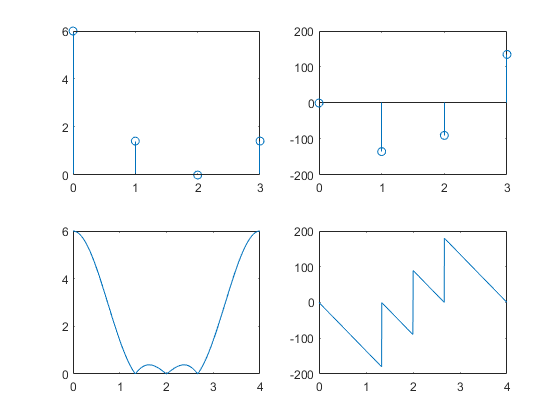

[X,w] = freqz(xn,1,1000,'whole');
Dw = 2*pi/N;
subplot(2,2,3);
plot(w/Dw,abs(X));
subplot(2,2,4);
plot(w/Dw,angle(X)*180/pi);

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

xn2 = [1, 2, 2, 1, zeros(1,12)];
N = 16;
Xk2 = dft(xn2,N);
magX = abs(Xk2)

magX =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaX = angle(Xk2)*180/pi

phaX =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


xn2 = idft(Xk2,N)

xn2 =    1.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 - 0.0000i   1.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


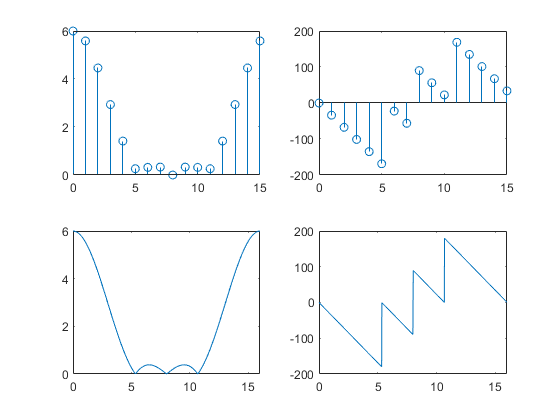

figure();
subplot(2,2,1);
stem(0:N-1, magX);
subplot(2,2,2);
stem(0:N-1, phaX);

[X2,w2] = freqz(xn2,1,1000,'whole');
Dw = 2*pi/N;
subplot(2,2,3);
plot(w/Dw, abs(X2));
subplot(2,2,4);
plot(w/Dw, angle(X2)*180/pi);

2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$


$$X_1 \left(k\right)=\sum_{n=0}^3 \overset{~}{x_1 } \left(n\right)e^{-j\frac{2\pi }{4}\mathrm{kn}}$$



$$X_1 \left(0\right)=\sum_{n=0}^3 \overset{~}{x_1 } \left(n\right)=4+1+\left(-1\right)+1=5$$



$$\begin{array}{l}
X_1 \left(1\right)=\sum_{n=0}^3 \overset{~}{x_1 } \left(n\right){\left(-j\right)}^n =4+\left(-j\right)+\left(-1\right)\left(-1\right)+j=5\\
X_1 \left(2\right)=\sum_{n=0}^3 \overset{~}{x_1 } \left(n\right){\left(-1\right)}^n =4+\left(-1\right)+\left(-1\right)+\left(-1\right)=1
\end{array}$$



$$X_1 \left(3\right)=\sum_{n=0}^3 \overset{~}{x_1 } \left(n\right){\left(j\right)}^n =4+j+\left(-1\right)\left(-1\right)+\left(-j\right)=5$$


xn1 = [4 1 -1 1];
N1 = 4;
Xk1 = dfs(xn1,N1)

Xk1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$


$$X_2 \left(k\right)=\sum_{n=0}^4 \overset{~}{x_2 } \left(n\right)e^{-j\frac{2\pi }{5}\mathrm{kn}}$$



$$X_2 \left(0\right)=\sum_{n=0}^4 \overset{~}{x_2 } \left(n\right)=1+0+\left(-1\right)+\left(-1\right)+0=-1$$



$$X_2 \left(1\right)=\sum_{n=0}^4 \overset{~}{x_2 } \left(n\right)e^{-j\frac{2\pi }{5}n} =1+0+\left(-1\right)e^{-j\frac{4\pi }{5}} +\left(-1\right)e^{-j\frac{6\pi }{5}} +0=1-e^{-j\frac{4\pi }{5}} -e^{-j\frac{6\pi }{5}} =2\ldotp 6180$$



$$X_2 \left(2\right)=\sum_{n=0}^4 \overset{~}{x_2 } \left(n\right)e^{-j\frac{4\pi }{5}n} =1+0+\left(-1\right)e^{-j\frac{8\pi }{5}} +\left(-1\right)e^{-j\frac{12\pi }{5}} +0=1-e^{-j\frac{8\pi }{5}} -e^{-j\frac{6\pi }{5}} =0\ldotp 3820$$



$$X_2 \left(3\right)=\sum_{n=0}^4 \overset{~}{x_2 } \left(n\right)e^{-j\frac{6\pi }{5}n} =1+0+\left(-1\right)e^{-j\frac{12\pi }{5}} +\left(-1\right)e^{-j\frac{18\pi }{5}} +0=1-e^{-j\frac{2\pi }{5}} -e^{j\frac{2\pi }{5}} =0\ldotp 3820$$



$$X_2 \left(4\right)=\sum_{n=0}^4 \overset{~}{x_2 } \left(n\right)e^{-j\frac{8\pi }{5}n} =1+0+\left(-1\right)e^{-j\frac{16\pi }{5}} +\left(-1\right)e^{-j\frac{24\pi }{5}} +0=1-e^{j\frac{4\pi }{5}} -e^{-j\frac{4\pi }{5}} =2\ldotp 6180$$


xn2 = [1 0 -1 -1 0];
N2 = 5;
Xk2 = dfs(xn2, N2)

Xk2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:100;
xn = (sinc((n-50)/2)).^2;
N = length(n);
Xk = dft(xn,N)

Xk =    1.9919 + 0.0000i  -1.9605 - 0.0610i   1.9167 + 0.1194i  -1.8732 - 0.1753i   1.8272 + 0.2285i  -1.7804 - 0.2791i   1.7317 + 0.3270i  -1.6822 - 0.3722i   1.6312 + 0.4145i  -1.5797 - 0.4541i   1.5269 + 0.4909i  -1.4738 - 0.5249i   1.4197 + 0.5560i  -1.3655 - 0.5843i   1.3105 + 0.6097i  -1.2558 - 0.6325i   1.2005 + 0.6522i  -1.1456 - 0.6694i   1.0905 + 0.6835i  -1.0360 - 0.6952i   0.9815 + 0.7038i  -0.9279 - 0.7101i   0.8745 + 0.7134i  -0.8222 - 0.7144i   0.7703 + 0.7126i  -0.7197 - 0.7086i   0.6698 + 0.7018i  -0.6214 - 0.6930i   0.5739 + 0.6815i  -0.5280 - 0.6682i   0.4832 + 0.6522i  -0.4403 - 0.6346i   0.3986 + 0.6146i  -0.3590 - 0.5930i   0.3208 + 0.5691i  -0.2847 - 0.5440i   0.2502 + 0.5167i  -0.2180 - 0.4884i   0.1876 + 0.4579i  -0.1595 - 0.4268i   0.1333 + 0.3936i  -0.1096 - 0.3602i   0.0879 + 0.3246i  -0.0687 - 0.2893i   0.0516 + 0.2518i  -0.0372 - 0.2151i   0.0248 + 0.1759i  -0.0151 - 0.1385i   0.0076 + 0.0978i  -0.0028 - 0.0608i


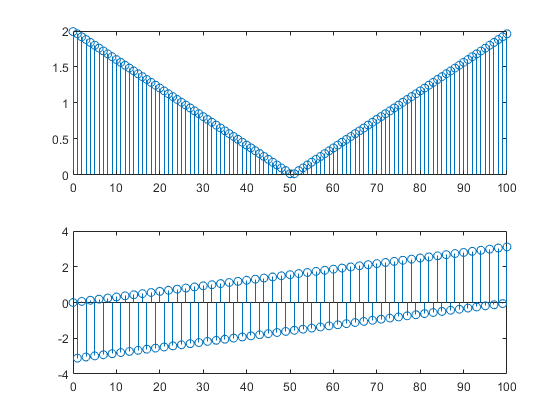

magX = abs(Xk);
phaX = angle(Xk);

figure();
subplot(2,1,1);
stem(0:N-1,magX);
subplot(2,1,2);
stem(0:N-1,phaX);

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

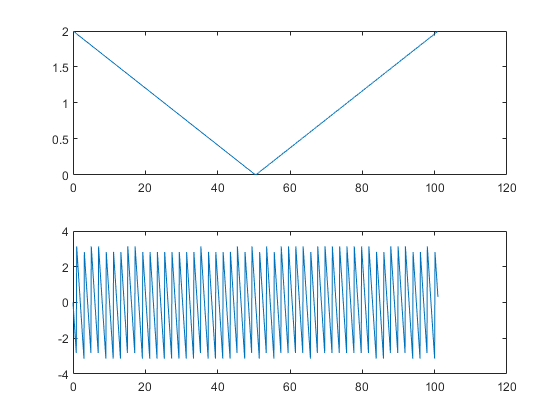

[X,w] = freqz(xn,1,1000,'whole');
Dw = 2*pi/N;
figure();
subplot(2,1,1);
plot(w/Dw,abs(X));
subplot(2,1,2);
plot(w/Dw,angle(X));

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

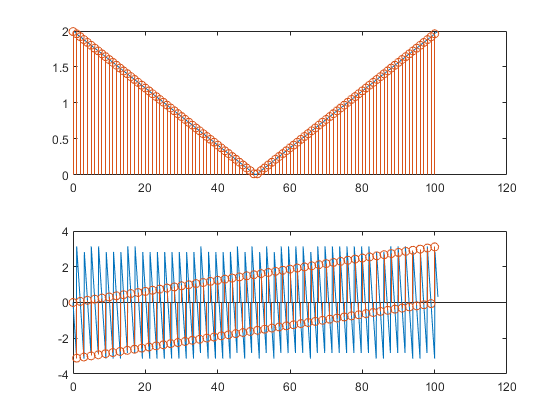

figure();
subplot(2,1,1);
plot(w/Dw,abs(X)); hold on;
stem(0:N-1,magX); hold off;
subplot(2,1,2);
plot(w/Dw,angle(X)); hold on;
stem(0:N-1,phaX); hold off;

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

DFT의 길이가 x(n)의 길이보다 같거나 크면 보간 공식을 이용하여 복원할 수 있다.


$$X\left(e^{j\omega } \right)=\sum_{k=0}^{N-1} X\left(k\right)\phi \left(\omega -\frac{2\pi k}{N}\right),\;\;\;\;\;\phi \left(\omega \right)=e^{-j\frac{\omega \left(N-1\right)}{2}} \frac{\sin \left(\omega \frac{N}{2}\right)}{N\;\sin \left(\frac{\omega }{2}\right)}$$


$N=101\;$이므로


$$X\left(e^{j\omega } \right)=\sum_{k=0}^{100} X\left(k\right)e^{-j\left(50\right)\omega } \frac{\sin \left(50\ldotp 5\omega \right)}{101\sin \left(\frac{\omega }{2}\right)}$$
